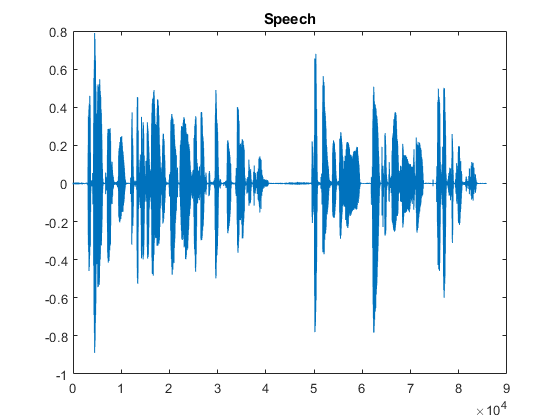

% lab14_ex_speech_compress.m
% Speech compression using linear prediction coding
clear all; close all;
warning('off')

ifigs = 1;             %  0/1 - to show figures inside the processing loop?

% Parameters
Mlen=256;              % length of analyzed block of samples
Mstep=180;             % offset between analyzed data blocks (in samples)
Np=2;                  % prediction order (IIR-AR filter order)
where=181;             % initial position of the first voiced excitation
roffset=20;            % offset in auto-correlation function when find max
compress=[0 0 0 0 0];           % table for calculated speech model coefficients
s=[];                  % the whole synthesized speech
ss=[];                 % one fragment of synthesized speech

% Read signal to compress
[x,fs]=audioread('mowa1.wav');	   % read speech signal (audio/wav/read)
figure; plot(x); title('Speech');  % display it


% debug
x(1:7100) = [];

% soundsc(x,fs); pause               % play it on loudspeakers (headphones)
N=length(x);                       % signal length
bs=zeros(1,Np);			   % synthesis filter buffer
Nblocks=floor((N-Mlen)/Mstep+1);   % number of speech blocks to be analyzed

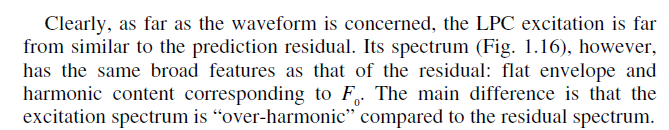

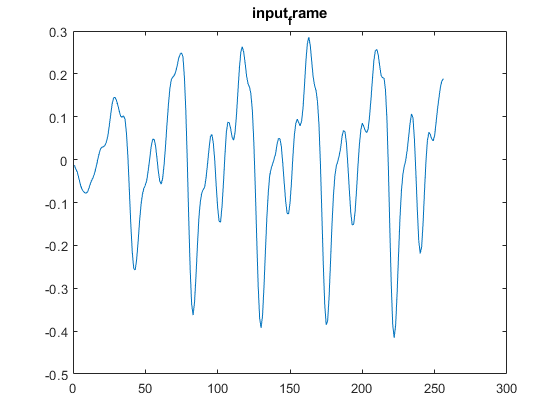

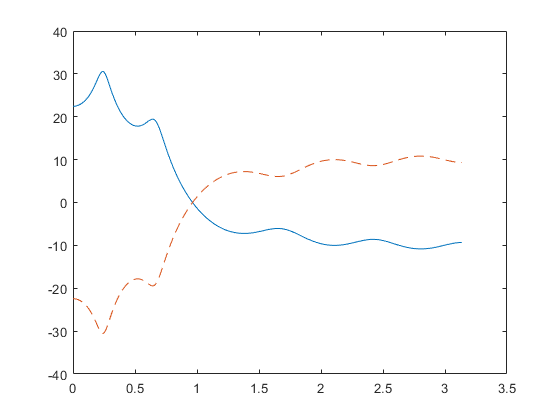

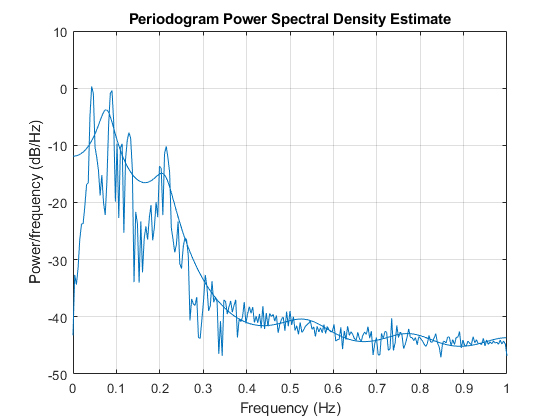

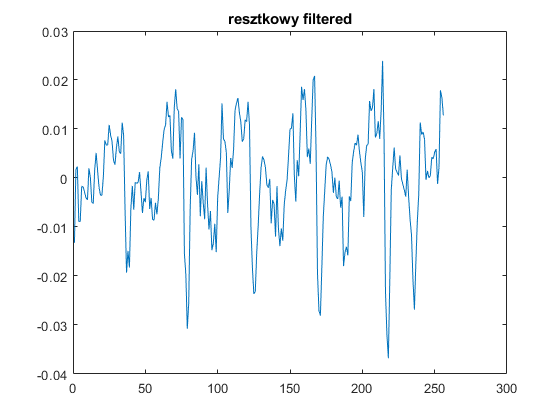

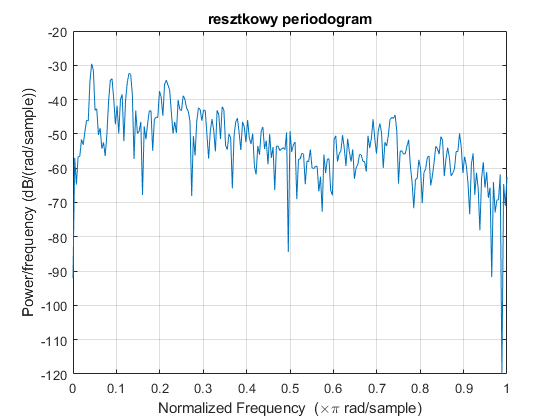

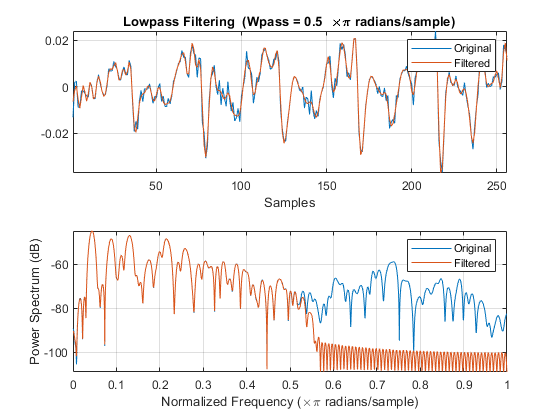

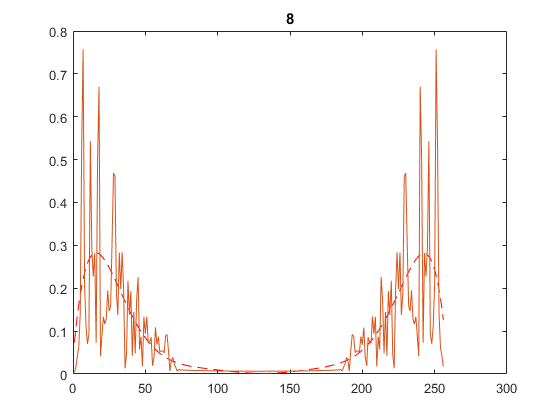

for  nr = 1 : Nblocks
    n = 1+(nr-1)*Mstep : Mlen + (nr-1)*Mstep;
    input_frame = x(n);
    % ANALYSIS - calculate speech model parameters
    % input_frame = input_frame - mean(input_frame);
    
    [ai, sigma_square] = lpc(input_frame,10); % mozna okno dodac
    sigma=sqrt(sigma_square);
    
    % filtry
    [HI, WI] = freqz(ai, 1, 512);
    [H, W] = freqz(1, ai, 512);
    
    if(ifigs==1)
        figure
        plot(input_frame); title("input_frame")
        
        figure
        plot(W, 20*log10(abs(H)), '-', WI, 20*log10(abs(HI)), '--')
        
        figure
        periodogram(input_frame,[],512,2)
        hold on;
        plot(W/pi,20*log10(sigma*abs(H)));
        hold off;
    end
    
    % resztokowy
    LP_residual=filter(ai,1,input_frame);
    
    if(ifigs==1)
        figure; plot(LP_residual); title("resztkowy filtered");
        figure; periodogram(LP_residual,[],512); title("resztkowy periodogram");
    end
    
    % fft resztkowego
    w = abs(fft(LP_residual));
    
    % filtr do wygladzania
    %a_smooth = fir1(Mlen/2,0.5,'low');
    %a_smooth = ones(1, Mlen)/Mlen;
    %[H_smooth, F_smooth] = freqz(a_smooth,1,128);
    
    % wygladzanie
    % w_smooth = real(filter(H_smooth, 1, LP_residual));
    LP_smooth = lowpass(LP_residual,0.5);
    w_smooth = abs(fft(LP_smooth));
    
    if(ifigs==1)
        figure; lowpass(LP_residual,0.5);
        %figure; plot(F_smooth, 20*log10(abs(H_smooth)))
        %figure; plot(w)
        %hold on
        %plot(abs(fft(w_smooth)), '--'); title("freq domain resztkowy");
    end
    
    % approx widma
    poly_degree = 8; poly_length = length(w_smooth);
    approx = polyfit(1:poly_length, w_smooth(1:poly_length)', poly_degree);
    
    w_approx = polyval(approx,1:poly_length);
    
    % plot approx
    if(ifigs==1)
        figure; plot(w_approx, 'r--');
        hold on
        plot(w_smooth);
        % xlim([0 50])
        title(poly_degree)
    end
    
    % proces decyzyjny: dzwieczna/bezdzwieczna
    %N0=pitch(input_frame);
    N0 = 1;
    if N0~=0
        %[~,I] = maxk(w_approx, 2)
        %excitation=zeros(Mstep,1);
        %for n=1:Mstep
        %    if mod(n,I(1)) == 0 || mod(n,I(1)) == 0
        %        excitation(n) = 1;    
        %    end
        %end
        %gain=sigma/sqrt(1/I(1));
        synt_frame = ifft(w_approx);
        gain = 0;excitation = 0;
    else
        % White Gaussian noise
        excitation=randn(180,1);
        gain=sigma;
        synt_frame=filter(gain,ai,excitation);
    end
    
    % syntetyk
    % synt_frame=filter(gain,ai,excitation);
    if(ifigs==1)
        figure
        plot(gain*excitation); title("gain*exc")
        figure
        plot(synt_frame);
        figure
        periodogram(synt_frame,[],512);
    end
    s;
end